# Universal function approximation using neural networks

## Activation functions

x = -8:0.1:8;

Sigmoid

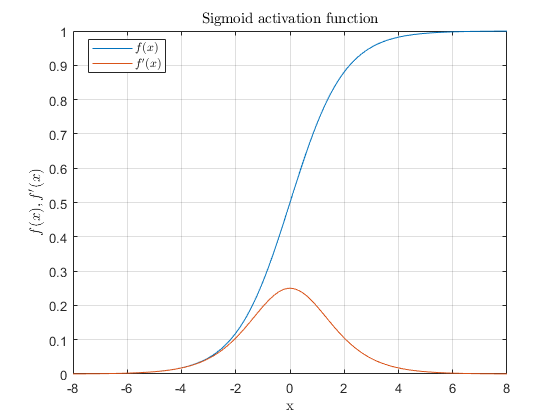

figure,
plot(x, sigmoid(x)); grid; hold on;
plot(x, sigmoid_derivative(x))
title("Sigmoid activation function", "Interpreter","latex")
xlabel("x", "Interpreter","latex")
ylabel("$f(x), f'(x)$", "Interpreter","latex")
legend("$f(x)$", "$f'(x)$", "interpreter", "latex", "Location","best");

Hyperbolic tangent

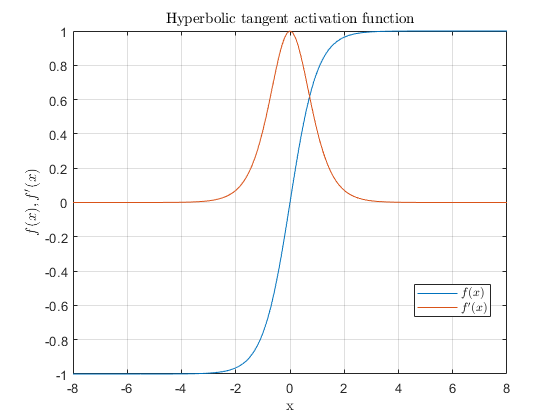

figure,
plot(x, tanh(x)); grid; hold on;
plot(x, tanh_derivative(x))
title("Hyperbolic tangent activation function", "Interpreter","latex")
xlabel("x", "Interpreter","latex")
ylabel("$f(x), f'(x)$", "Interpreter","latex")
legend("$f(x)$", "$f'(x)$", "interpreter", "latex", "Location","best");

## XOR problem using neural networks

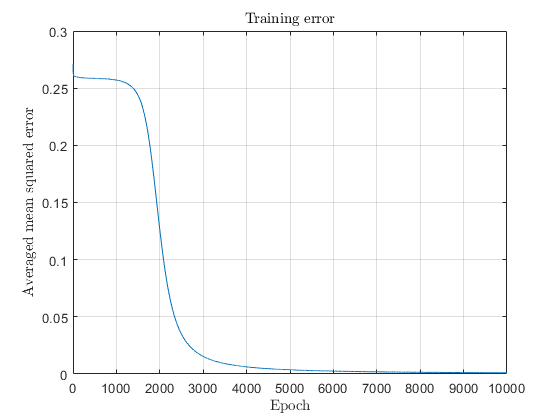

learning_rate = 0.1;

dense_layer = Dense(2, 5, "AllowBias", true, "LearningRate", learning_rate, "Momentum", 0.1);
dense_layer_activation = Activation(@sigmoid, @sigmoid_derivative);
output_layer = Dense(5, 1, "AllowBias", true, "LearningRate", learning_rate, "Momentum", 0.1);
output_layer_activation = Activation(@sigmoid, @sigmoid_derivative);

x = [0 1 0 1; 0 0 1 1];
y = [0 1 1 0];

number_of_epochs = 10000;
training_loss = zeros(number_of_epochs, 1);

for j = 1:number_of_epochs
    loss = 0;
    for i = 1:length(y)
        % inferece
        [y_hat, dense_layer] = dense_layer.forward(x(:, i));
        [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
        [y_hat, output_layer] = output_layer.forward(y_hat);
        [y_hat, output_layer_activation] = output_layer_activation.forward(y_hat);
        
        loss = loss + mean_squared_error(y(i), y_hat);
        
        % back propagation
        [gradient, output_layer_activation] = output_layer_activation.backward( ...
            mean_squared_error_derivative(y(i), y_hat));
        [gradient, output_layer] = output_layer.backward(gradient);
        [gradient, dense_layer_activation] = dense_layer_activation.backward(gradient);
        [~, dense_layer] = dense_layer.backward(gradient);
    end
    training_loss(j) = loss/length(y);
end

figure, 
plot(training_loss); grid;
title("Training error", "Interpreter","latex");
ylabel("Averaged mean squared error", "Interpreter","latex");
xlabel("Epoch", "Interpreter","latex");

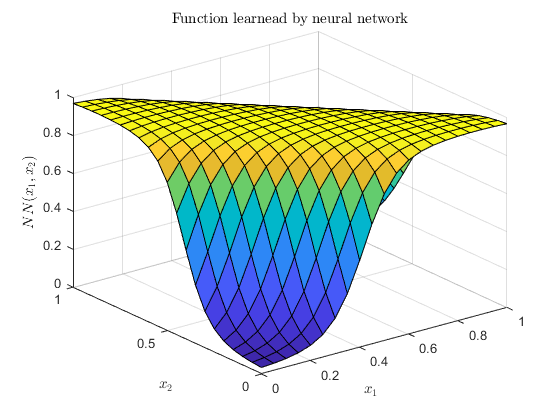


x = 0:0.05:1;
[X, Y] = meshgrid(x, x);
out = zeros(size(X));

[number_of_rows, number_of_culoms] = size(X);
for i = 1:number_of_rows
    for j = 1:number_of_culoms
        [y_hat, dense_layer] = dense_layer.forward([X(i, j) Y(i, j)]');
        [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
        [y_hat, output_layer] = output_layer.forward(y_hat);
        [y_hat, output_layer_activation] = output_layer_activation.forward(y_hat);
        out(i, j) = y_hat;
    end
end

figure, 
surf(X, Y, out);
title("Function learnead by neural network", "Interpreter","latex");
xlabel("$x_1$", "Interpreter","latex");
ylabel("$x_2$", "Interpreter","latex");
zlabel("$NN(x_1,x_2)$", "Interpreter","latex");

## Function Approximation using neural networks

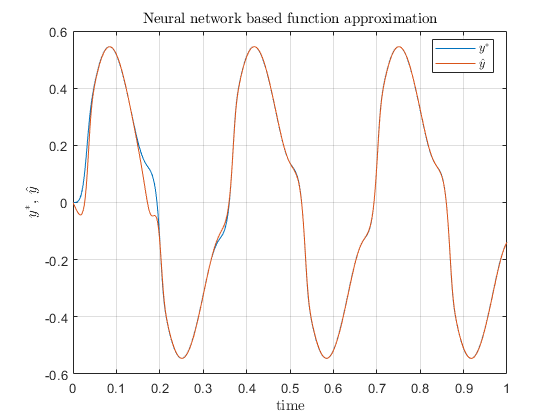

t = 0:0.001:1;
u = 0.5*sin(6*pi*t);
y = zeros(size(u));
y_prev = 0;

hidden_layer_size = 6;
W = rands(hidden_layer_size, 2);
Wo = rands(1, hidden_layer_size);
W_prev = W;
Wo_prev = Wo;

lr = 0.5;
m = 0.05;

y_hat = zeros(size(u));
e = zeros(size(u));

activation = @tanh;
activation_derivative = @tanh_derivative;

for i = 1:length(t)
    y(i) = u(i)^3 + y_prev/(1 + y_prev^2);
    y_prev = y(i);
    X = [u(i) y(i)]';
    A = W*X;
    Z = activation(A);
    y_hat(i) = Wo*Z;
    
    e(i) = y(i) - y_hat(i);
    
    dWo = lr*e(i)*Z';
    dW = lr*e(i)*(Wo'.*activation_derivative(A)).*X';
    
    aux_Wo = Wo;
    Wo = Wo + dWo + m*(Wo - Wo_prev);
    Wo_prev = aux_Wo;
    
    aux_W = W;
    W = W + dW + m*(W - W_prev);
    W_prev = aux_W; 
end

figure,
plot(t, y); grid; hold on;
plot(t, y_hat);
title("Neural network based function approximation", "Interpreter","latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^*,\;\hat{y}$", "Interpreter","latex");
legend("$y^*$", "$\hat{y}$", "Interpreter", "latex", "Location","best");

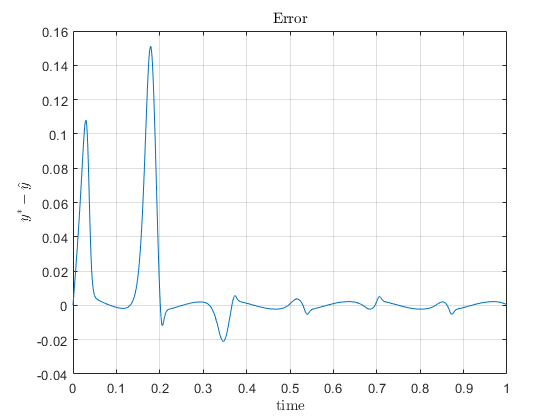


figure, 
plot(t, e); grid;
title("Error", 'Interpreter',"latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^* - \hat{y}$", "Interpreter","latex");

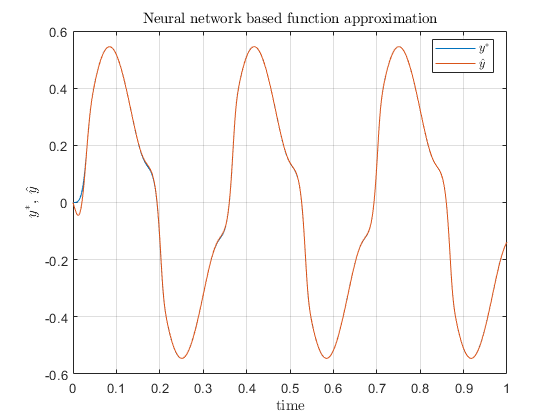

t = 0:0.001:1;
u = 0.5*sin(6*pi*t);
y = zeros(size(u));
y_prev = 0;

for i = 1:length(t)
    y(i) = u(i)^3 + y_prev/(1 + y_prev^2);
    y_prev = y(i);
end

learning_rate = 0.5;
momentum = 0.05;

dense_layer = Dense(2, 6, "AllowBias", false, "LearningRate", learning_rate, "Momentum", momentum);
dense_layer_activation = Activation(@tanh, @tanh_derivative);
output_layer = Dense(6, 1, "AllowBias", false, "LearningRate", learning_rate, "Momentum", momentum);

number_of_epochs = 1;
training_loss = zeros(number_of_epochs, 1);

loss = zeros(size(y));
y_hat = zeros(size(y));

for i = 1:length(y)
    % inferece
    [x, dense_layer] = dense_layer.forward([u(i) y(i)]');
    [x, dense_layer_activation] = dense_layer_activation.forward(x);
    [y_hat(i), output_layer] = output_layer.forward(x);
    
    loss(i) = y(i) - y_hat(i);
    
    % back propagation
    [gradient, output_layer] = output_layer.backward(mean_squared_error_derivative(y(i), y_hat(i)));
    [gradient, dense_layer_activation] = dense_layer_activation.backward(gradient);
    [~, dense_layer] = dense_layer.backward(gradient);
end


figure,
plot(t, y); grid; hold on;
plot(t, y_hat);
title("Neural network based function approximation", "Interpreter","latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^*,\;\hat{y}$", "Interpreter","latex");
legend("$y^*$", "$\hat{y}$", "Interpreter", "latex", "Location","best");

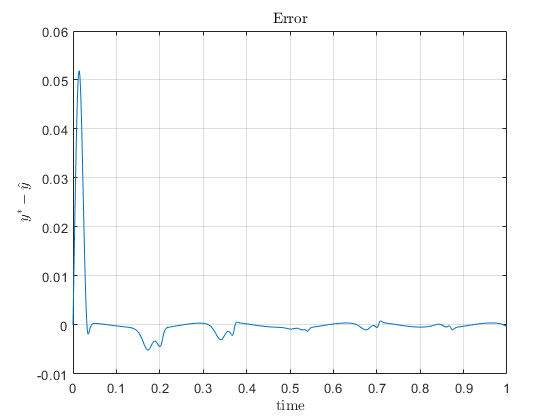


figure, 
plot(t, loss); grid;
title("Error", 'Interpreter',"latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^* - \hat{y}$", "Interpreter","latex");

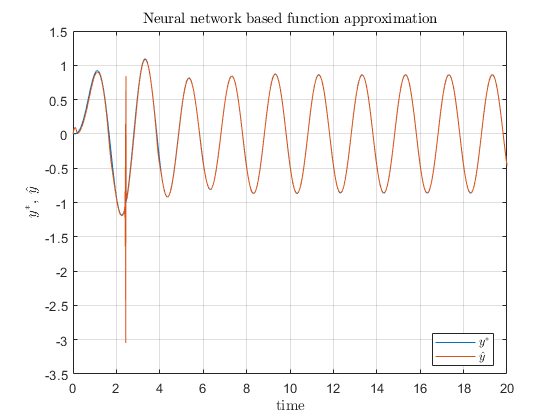

H = tf(10, [1 1 5]);
Ts = 0.01;
Hd = c2d(H, Ts, 'zoh');
[num, den] = tfdata(Hd, 'v');

t = 0:Ts:20;
u = 0.5*sin(pi*t);
y = dlsim(num, den, u);

hidden_layer_size = 16;
W = rands(hidden_layer_size, 2);
Wo = rands(1, hidden_layer_size);
W_prev = W;
Wo_prev = Wo;

lr = 0.5;
m = 0.01;

y_hat = zeros(size(u));
e = zeros(size(u));

activation = @tanh;
activation_derivative = @tanh_derivative;

for i = 1:length(t)
    X = [u(i) y(i)]';
    A = W*X;
    Z = activation(A);
    y_hat(i) = Wo*Z;
    
    e(i) = y(i) - y_hat(i);
    
    dWo = lr*e(i)*Z';
    dW = lr*e(i)*(Wo'.*activation_derivative(A)).*X';
    
    aux_Wo = Wo;
    Wo = Wo + dWo + m*(Wo - Wo_prev);
    Wo_prev = aux_Wo;
    
    aux_W = W;
    W = W + dW + m*(W - W_prev);
    W_prev = aux_W; 
end

figure,
plot(t, y); grid; hold on;
plot(t, y_hat);
title("Neural network based function approximation", "Interpreter","latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^*,\;\hat{y}$", "Interpreter","latex");
legend("$y^*$", "$\hat{y}$", "Interpreter", "latex", "Location","best");

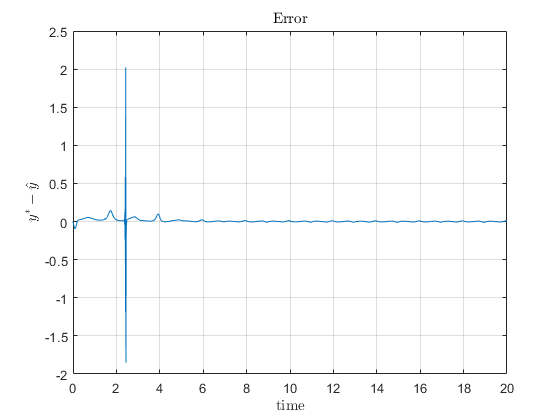


figure, 
plot(t, e); grid;
title("Error", 'Interpreter',"latex");
xlabel("time", "Interpreter","latex");
ylabel("$y^* - \hat{y}$", "Interpreter","latex");

function y = sigmoid(x)
    y = 1./(1 + exp(-x));
end

function y = sigmoid_derivative(x)
    y = sigmoid(x).*(1 - sigmoid(x));
end

function y = tanh(x)
    y = (exp(x) - exp(-x))./(exp(x) + exp(-x));
end

function y = tanh_derivative(x)
    y = (1 - tanh(x).^2);
end

function e = mean_squared_error(y, y_hat)
    e = sum((y - y_hat).^2)/length(y);
end

function e = mean_squared_error_derivative(y, y_hat)
    e = (2/length(y))*(y_hat' - y');
end